# DC Motor Model Parameters

DC Motor Model Parameters & Initialization

Author: Muhammad Taha Ansari

Project: Model-Based Design of DC Motor Speed Controller

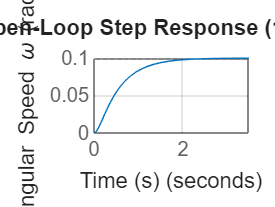

clear; clc;

%% 1. Physical Parameters
R = 1.0;     % Armature resistance [Ohms]
L = 0.5;     % Armature inductance [Henry]
Kt = 0.01;   % Torque constant [N-m/A]
Ke = 0.01;   % Back-EMF constant [V-s/rad]
J = 0.01;    % Rotor moment of inertia [kg-m^2]
b = 0.1;     % Viscous friction coefficient [N-m-s/rad]

%% 2. Continuous State-Space Representation
% State vector: x = [omega; i] (Angular Velocity, Current)
% Input: u = V (Armature Voltage)
% Output: y = omega (Angular Velocity)

A = [-b/J Kt/J
     -Ke/L -R/L];

B = [0;
     1/L];

C = [1, 0];

D = 0;

% Create Continuous State-Space System
sys_dc = ss(A, B, C, D);

%% 3. Open-Loop Step Response Check
figure(1);
step(sys_dc);
title('Open-Loop Step Response (1V Input)');
xlabel('Time (s)');
ylabel('Angular Speed \omega (rad/s)');
grid on;


disp('DC Motor State-Space Model successfully initialized!');

DC Motor State-Space Model successfully initialized!


## Steady-State Analysis:

The steady-state gain tells you how much angular speed is produced per volt of armature voltage.

Kdc = dcgain(sys_dc)

Kdc = 0.0999

Effect of different input voltages.

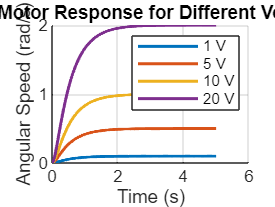

t = 0:0.01:5;

figure;
hold on;

for V = [1 5 10 20]
    [y,tout] = step(V*sys_dc,t);
    plot(tout,y,'LineWidth',1.5, ...
        'DisplayName',sprintf('%g V',V));
end

xlabel('Time (s)');
ylabel('Angular Speed (rad/s)');
title('DC Motor Response for Different Voltages');
legend('show');
grid on;
hold off;

Steady-state error without a controller

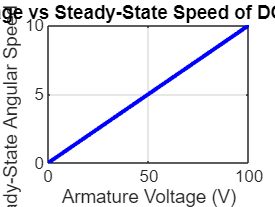


%% Voltage vs Steady-State Speed
clc;
close all;

% Define input voltage range
V = 0:1:100;   % Voltage from 0 to 100 V

% Calculate DC gain of motor
Kdc = dcgain(sys_dc);

% Calculate steady-state speed
omega_ss = Kdc * V;

% Plot
figure;

plot(V, omega_ss, 'b-', 'LineWidth', 2);

xlabel('Armature Voltage (V)');
ylabel('Steady-State Angular Speed (rad/s)');
title('Voltage vs Steady-State Speed of DC Motor');

grid on;
box on;


% Display DC gain
fprintf('DC Motor Gain = %.4f rad/s/V\n', Kdc);

DC Motor Gain = 0.0999 rad/s/V


## Settling time and rise time

Steady-state analysis describes the final equilibrium, while transient analysis describes how the motor gets there.

info = stepinfo(sys_dc);

disp(info)

         RiseTime: 1.1351
    TransientTime: 2.0652
     SettlingTime: 2.0652
      SettlingMin: 0.0899
      SettlingMax: 0.0998
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0998
         PeakTime: 3.6758



Check the poles and stability

pole(sys_dc)

ans =    -9.9975
   -2.0025


## External Load as an Input

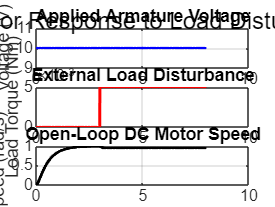

Bt = [0 -1/J;
     1/L 0];

sys_dc_t = ss(A, Bt, C, D);

sys_dc_t.InputName = {'Voltage','Load Torque'};
sys_dc_t.OutputName = 'Angular Speed';

%% 3. Simulation Time
t = (0:0.01:8)';

%% 4. Input Signals
V = 10 * ones(size(t));

% Load torque applied at 3 seconds
TL = 0.005 * double(t >= 3);

% Combine the two inputs
u = [V TL];

%% 5. Simulate Open-Loop Motor
[y, tout, x] = lsim(sys_dc_t, u, t);

omega = y;

%% 6. Plot Results
figure;

subplot(3,1,1);
plot(tout, V, 'b', 'LineWidth', 1.5);
ylabel('Voltage (V)');
title('Applied Armature Voltage');
grid on;

subplot(3,1,2);
plot(tout, TL, 'r', 'LineWidth', 1.5);
ylabel('Load Torque (Nm)');
title('External Load Disturbance');
grid on;

subplot(3,1,3);
plot(tout, omega, 'k', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Speed (rad/s)');
title('Open-Loop DC Motor Speed');
grid on;

sgtitle('DC Motor Response to Load Disturbance');


%% 7. Display Steady-State Values
omega_before = (Kt*10)/(R*b + Kt*Ke);

omega_after = (Kt*10 - R*0.005) / ...
              (R*b + Kt*Ke);

fprintf('Speed before load = %.4f rad/s\n', ...
        omega_before);

Speed before load = 0.9990 rad/s



fprintf('Speed after load  = %.4f rad/s\n', ...
        omega_after);

Speed after load  = 0.9491 rad/s



fprintf('Speed reduction   = %.4f rad/s\n', ...
        omega_before - omega_after);

Speed reduction   = 0.0500 rad/s


Adding an External Load in the open loop dc motor, the output speed reduces. This is further inhances the need of a closed loop controller so that the motor is not only maintain the output speed when experices the load but also can track the reference speed.

Before designing the Controller.

% Select voltage input only
sys_voltage = sys_dc_t(:,1);

% Analyze open-loop step response
info = stepinfo(sys_voltage);

disp(info);

         RiseTime: 1.1351
    TransientTime: 2.0652
     SettlingTime: 2.0652
      SettlingMin: 0.0899
      SettlingMax: 0.0998
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0998
         PeakTime: 3.6758




% Display system poles
disp(pole(sys_voltage));

   -9.9975
   -2.0025




% Display steady-state gain
disp(dcgain(sys_voltage));

    0.0999



## Controller